# The Bridge of Doom challenge

#### Authors: Dexter Friis-Hecht, Dokyun Kim, Ellen Sun

!!! MATLAB Symbolic Toolbox is required to run the livescript !!!

Given an equation of the parametric curve C, program the Neato so it safely drives over it without falling off. 

The curve is defined below.


$$C(t)_i = 0.3960*cos (2.65(0.2t+1.4))$$



$$C(t)_j = -0.99*sin(0.2t+1.4)$$


% Define symbolic variables

clc
syms a b t r
assume(t,'real') % parameter u should be real

% Defining the parametric curve's vector components

ri = 0.3960*cos(2.65*(0.2*t+1.4)); % i vector component
rj = -0.99*sin(0.2*t+1.4); % j vector component
rk = 0*t; % k vector component
r=[ri,rj,rk] % combined parametric curve

$$r = \left(\begin{array}{ccc} \frac{99\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{250} & -\frac{99\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{100} & 0 \end{array}\right)$$

## Linear speed($V$) and angular velocity($\omega$)

To program the Neato, we need to calculate the correct left & right wheel velocity. In order to calculate wheel velocities, we have to calculate linear speed ($V$) and angular velocity ($\omega$).

Linear speed (V) is defined as the magnitude of velocity (v).


$$v = \frac{dr}{dt{$$



$$V= \|v\|$$


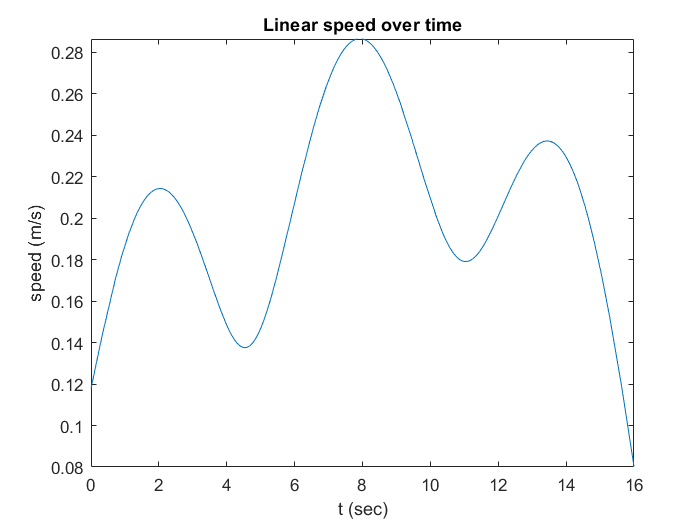

% Calculating linear speed
drdt = diff(r, t);
linear_velocity = drdt;
lin_speed = norm(drdt);

% Graph
figure()
fplot(lin_speed, [0 16])
ylabel("speed (m/s)")
xlabel("t (sec)")
title("Linear speed over time")

Angular velocity ($\left.\omega \right)$ is defined as


$$\omega = \hat{T} \times \frac{d\hat{T}}{dt}$$


where T is the unit tangent vector defined as


$$\hat{T} = \frac{v(t)}{V(t)}$$


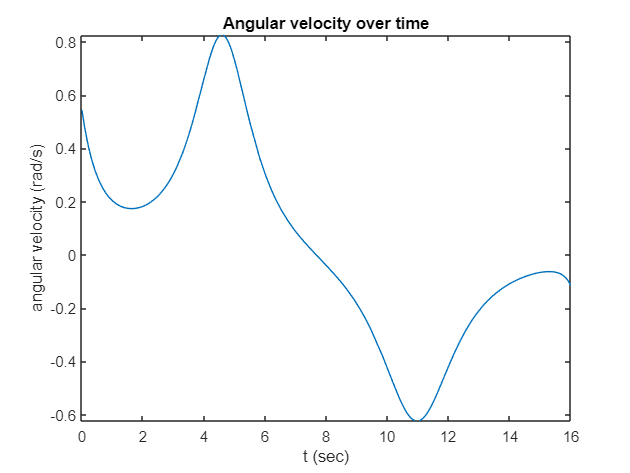

% Calculating angular velocity
T = linear_velocity ./ lin_speed;
dTdt = diff(T,t);

angular_velocity = (cross(T,dTdt));

% Graph
figure()
fplot(angular_velocity(3), [0 16])
ylabel("angular velocity (rad/s)")
xlabel("t (sec)")
title("Angular velocity over time")

## Parametric curve with Normal & Tangent vectors

The normal vectors of a parametric curve is defined as:


$$\hat{N} = \frac{\hat{T'}}{\|\hat{T'}\|}$$


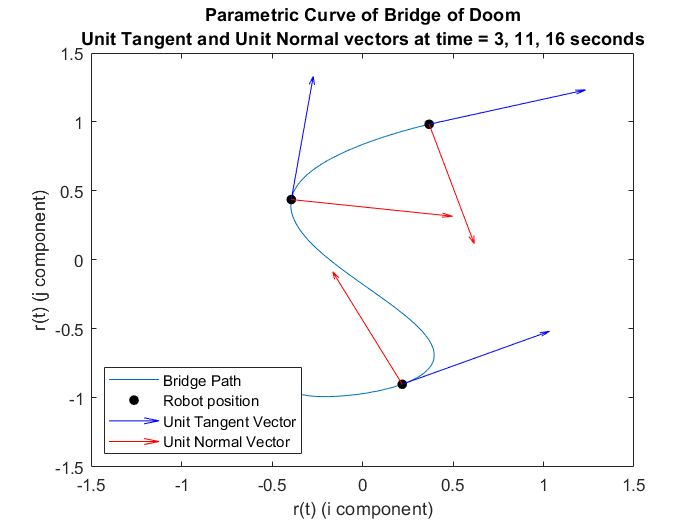

normal_vector = dTdt./norm(dTdt);

figure()
fplot(ri, rj, [0 16])
ylabel("r(t) (j component)")
xlabel("r(t) (i component)")
title("Parametric Curve of Bridge of Doom"+ newline + "Unit Tangent and Unit Normal vectors at time = 3, 11, 16 seconds")
hold on;

times = [3,11,16]; %plot T and N at specific times
for time = times 

    %Calculate starting point for tangent and unit vector
    i0 = double(subs(ri,{t},{time}));
    j0 = double(subs(rj,{t},{time}));
    plot(i0,j0,'.',MarkerSize=20,Color='black') %plot it as a point

    %Calculate end point for tangent vector
    Ti = T(1); %isolate i component
    Tj = T(2); %isolate j component
    Ti_cords = double(subs(Ti,{t},{time})); %calculate i component
    Tj_cords = double(subs(Tj,{t},{time})); %calculate j component

    %Calculate end point for normal vector
    Ni = normal_vector(1); %isolate i component
    Nj = normal_vector(2); %isolate j component
    Ni_cords = double(subs(Ni,{t},{time})); %calculate i component
    Nj_cords = double(subs(Nj,{t},{time})); %calculate j component
    
    quiver(i0,j0,Ti_cords,Tj_cords,Color='blue') %plot tangent vector
    quiver(i0,j0,Ni_cords,Nj_cords,Color='red') %plot normal vector
    legend('Bridge Path','Robot position','Unit Tangent Vector', 'Unit Normal Vector',Location='southwest')
end

%set axis size
domain = 1.5;
axis([-domain domain -domain domain])

hold off;

## Left & Right wheel velocity ($v_l$ , $v_r$)

 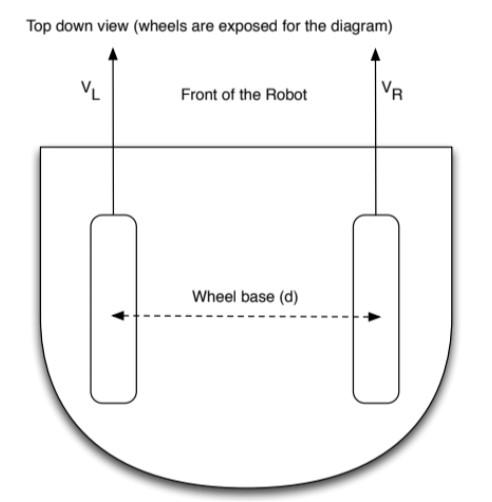

Assuming no wheel slippage, the linear speed (V) and angular velocity ($\omega$) can be expressed in terms of $v_l$ and $v_r$,


$$V = \frac{v_l+v_r}{2}$$



$$\omega = \frac{v_r-v_l}{d}$$


where d is the distance between two wheels.

The equation above can be rearranged to express $v_l$ and $v_r$ in terms of V and $\omega$.


$$v_l =  V-\omega\frac{d}{2}$$



$$v_r = V + \omega\frac{d}{2}
$$


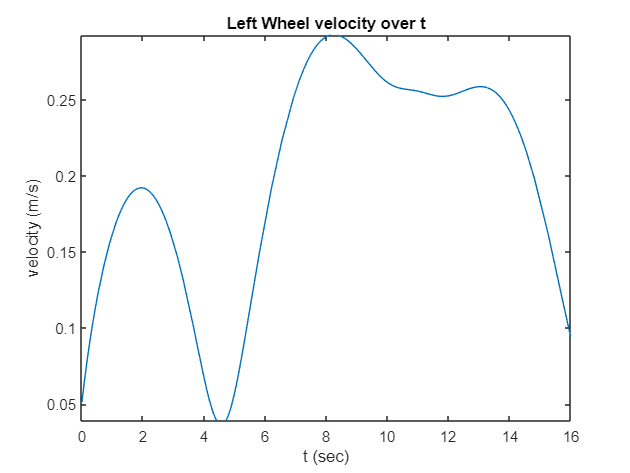

% Calculating left & right wheel velocity
d = 0.245;
velocity_left = lin_speed - (angular_velocity) * (d / 2);
velocity_right = lin_speed + (angular_velocity) * (d / 2);

% Graph
fplot(velocity_left(3), [0 16])
ylabel("velocity (m/s)")
xlabel("t (sec)")
title("Left Wheel velocity over t")

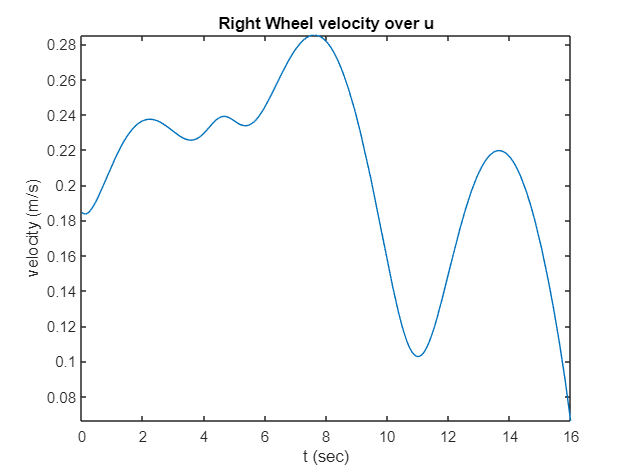

fplot(velocity_right(3), [0 16])
ylabel("velocity (m/s)")
xlabel("t (sec)")
title("Right Wheel velocity over u")

**!!! Run ALL sections above before progressing !!!**

## Encoder Data vs Theoretical Values

**!!! Run *****neato_controller.m***** with a physical Neato before running. Using a simulation will cause some graphs to fail. !!!**

Using data from the Neato's encoder, we can compare the theoretical and experimental values for the path, speed, wheel velocity, and angular velocity. 

The Neato's encoder array has time, distance traveled by left wheel, and distance traveled by right wheel in each column. 

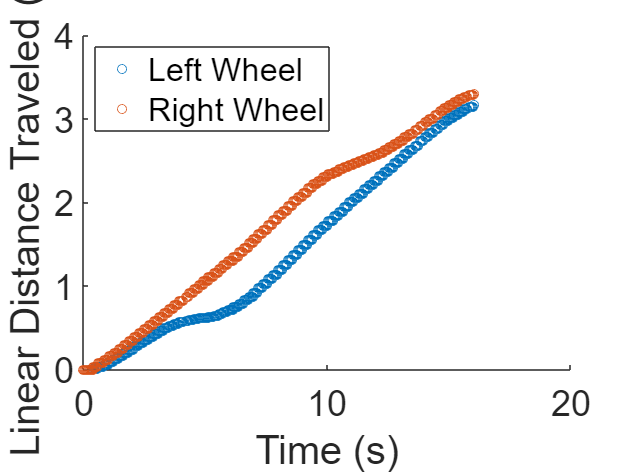

% Plot raw encoder data
encoder_time = encoder_data(:,1);
encoder_ldist = encoder_data(:,2);
encoder_rdist = encoder_data(:,3);
figure()
scatter(encoder_data(:,1),encoder_data(:,2:3));
set(gca,'FontSize',24);
xlabel("Time (s)")
ylabel("Linear Distance Traveled (m)")
legend('Left Wheel','Right Wheel','Location','northwest');

Using distance traveled by each wheel $r_{l,r}(t)$, we will recreate wheel velocity, linear speed, angular velocity, and the path.

**Velocity** of each wheel is simply the derivative of $r_{l,r}(t)$.


$$v_{l,r} = \frac{dr_{l,r}}{dt}$$


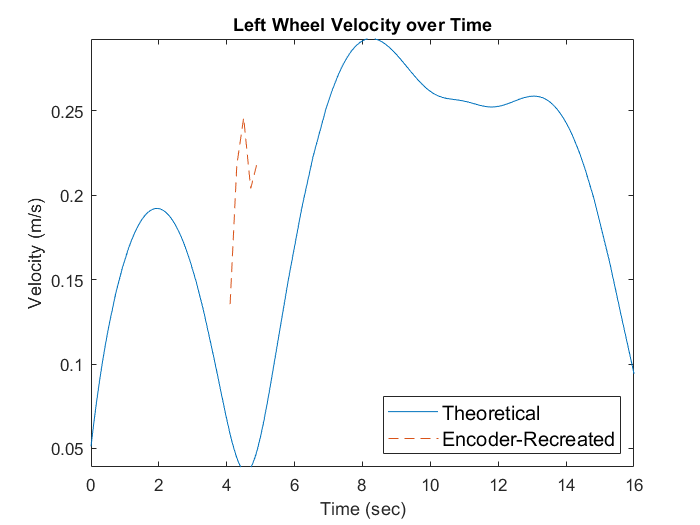

dr_left = diff(encoder_ldist);
dr_right = diff(encoder_rdist);
dt = diff(encoder_time);

encoder_velLeft = dr_left./dt;
encoder_velRight = dr_right./dt;

% Noise filtering
fltrd_velLeft = filterSpeed(encoder_velLeft,encoder_time,0.3);
fltrd_velRight = filterSpeed(encoder_velRight,encoder_time,0.3);

% Compare to theoretical velocity
figure()
fplot(velocity_left(3), [0 16])
hold on;
plot(fltrd_velLeft(:,1), fltrd_velLeft(:,2), "--")
hold off;
ylabel("Velocity (m/s)")
xlabel("Time (sec)")
title("Left Wheel Velocity over Time")
legend("Theoretical","Encoder-Recreated","fontsize", 12, "Location", "southeast")

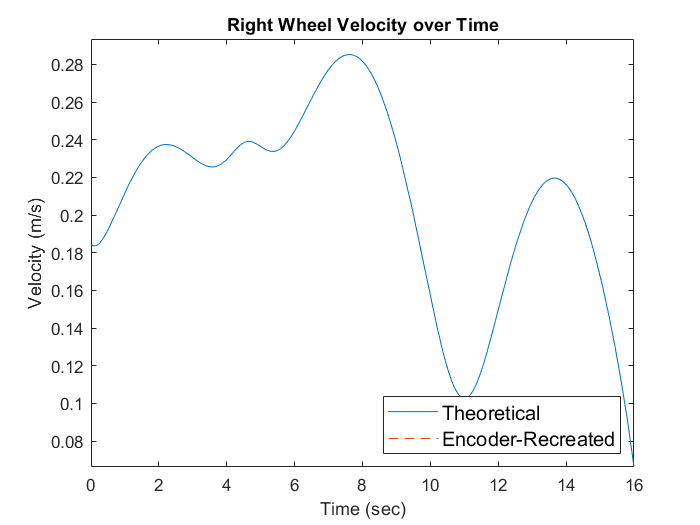


figure()
fplot(velocity_right(3), [0 16])
hold on;
plot(fltrd_velRight(:,1), fltrd_velRight(:,2), "--")
hold off;
ylabel("Velocity (m/s)")
xlabel("Time (sec)")
title("Right Wheel Velocity over Time")
legend("Theoretical","Encoder-Recreated","fontsize", 12, "Location", "southeast")

**Linear speed** can be expressed in terms of $v_l$ and $v_r$.


$$V = \frac{v_l+v_r}{2$$


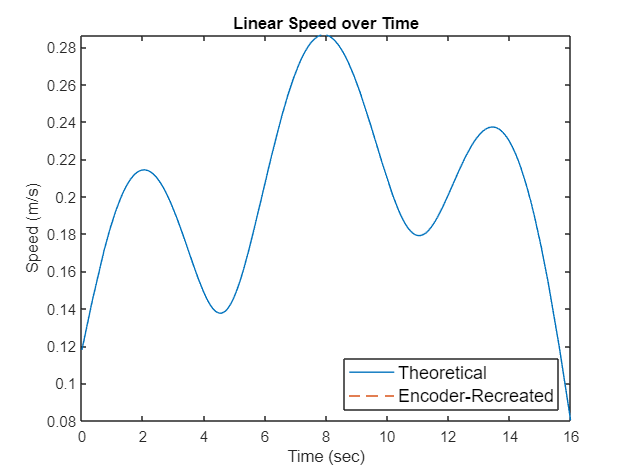

encoder_linSpd = (encoder_velLeft+encoder_velRight)/2;

% Noise filtering
fltrd_linSpd = filterSpeed(encoder_linSpd, encoder_time,0.3);

% Compare to theoretical speed
figure()
fplot(lin_speed, [0 16])
hold on;
plot(fltrd_linSpd(:,1),fltrd_linSpd(:,2),'--')
hold off;
ylabel("Speed (m/s)")
xlabel("Time (sec)")
title("Linear Speed over Time")
legend("Theoretical","Encoder-Recreated","fontsize", 12, "Location", "southeast")

**Angular velocity **can be expressed in terms of $v_l$,$v_r$, and the distance between two wheels ($d$).


$$\omega = \frac{v_r-v_l}{d}$$


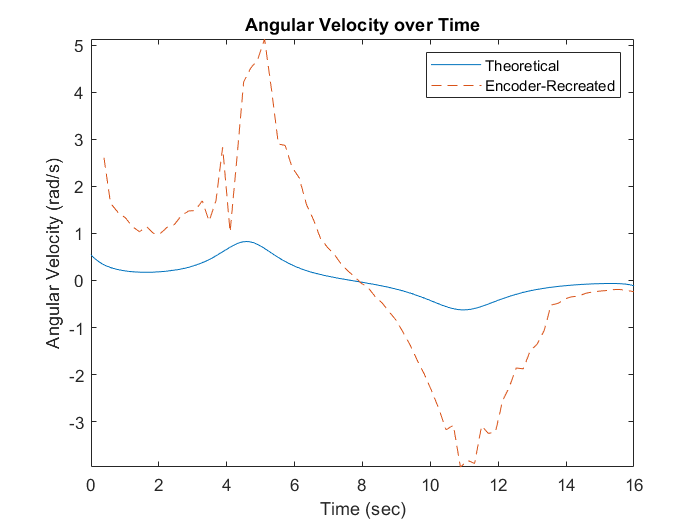

encoder_angVel = (encoder_velRight-encoder_velLeft)/d;

% Noise filtering
fltrd_angVel = filterSpeed(encoder_angVel,encoder_time,100000); % Only filter out zeros

% Compare to theoretical velocity
figure()
fplot(angular_velocity(3), [0 16])
hold on;
plot(fltrd_angVel(:,1),fltrd_angVel(:,2),"--");
hold off;
ylabel("Angular Velocity (rad/s)")
xlabel("Time (sec)")
title("Angular Velocity over Time")
legend("Theoretical", "Encoder-Recreated")

The **path **can be calculated using linear speed.


$$x_{i+1} = x_i + Vcos(\theta_i)\Delta t$$



$$y_{i+1} = y_i + Vsin(\theta_i)\Delta t$$


where 


$$\theta_{i+1} = \theta_i + \omega\Delta t$$


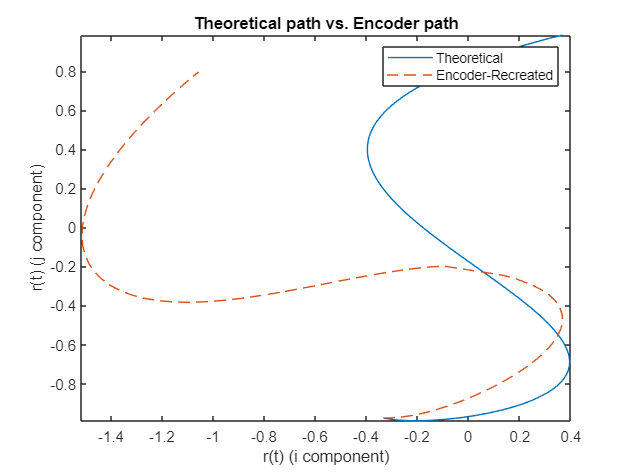

x_pos = zeros(length(encoder_time)-1,1);
y_pos = zeros(length(encoder_time)-1,1);

% Initial condition, i=1
theta_i = 0;
x_i = -0.3337;
y_i = -0.9756;

x_pos(1) = x_i;
y_pos(1) = y_i;

for i = 2:length(encoder_time)-1
    V_i = encoder_linSpd(i);
    delta_t = encoder_time(i) - encoder_time(i-1);
    delta_t = delta_t/0.2;
    x_i = x_i + V_i*cos(theta_i)*delta_t;
    y_i = y_i + V_i*sin(theta_i)*delta_t;
    theta_i = theta_i + encoder_angVel(i)*delta_t;
    x_pos(i,1) = x_i;
    y_pos(i,1) = y_i;
end

figure()
fplot(ri, rj, [0 16])
hold on;
plot(x_pos, y_pos, "--")
hold off;
ylabel("r(t) (j component)")
xlabel("r(t) (i component)")
title("Theoretical path vs. Encoder path")
legend("Theoretical", "Encoder-Recreated")